load  'pub_dataset5.mat'
tic

n = numel(data_tr(:,19));
rng(1) % For reproducibility
idx = randsample(n,n);
X = data_tr(idx,1:18);
Y = data_tr(idx,19);

initobs = 7;
Mdl = incrementalClassificationNaiveBayes('MaxNumClasses',2,'MetricsWindowSize',1000,...
    'Metrics','classiferror','MetricsWarmupPeriod',initobs);

Mdl = fit(Mdl,X(1:initobs,:),Y(1:initobs));

haveTrainedAllClasses = numel(unique(Y(1:initobs))) == 2

haveTrainedAllClasses = logical
   1


Preallocation

numObsPerChunk = 7;
nchunk = floor((n - initobs)/numObsPerChunk);
mu21 = zeros(nchunk,1);
ce = array2table(nan(nchunk,2),'VariableNames',["Cumulative" "Window"]);
trained = false(nchunk,1);

% Incremental fitting
for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1 + initobs);
    iend   = min(n,numObsPerChunk*j + initobs);
    idx = ibegin:iend;
    Mdl = updateMetrics(Mdl,X(idx,:),Y(idx));
    ce{j,:} = Mdl.Metrics{"ClassificationError",:};
    if ce{j,"Window"} > 0.005
        Mdl = fit(Mdl,X(idx,:),Y(idx));
        trained(j) = true;
    end
    mu21(j) = Mdl.DistributionParameters{2,1}(1);
end

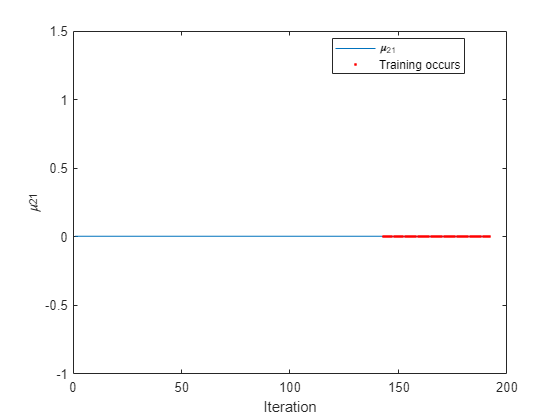

figure(1); 
plot(mu21)
hold on
plot(find(trained),mu21(trained),'r.')
ylabel('\mu_{21}')
xlabel('Iteration') 
legend('\mu_{21}','Training occurs','Location','best')
hold off

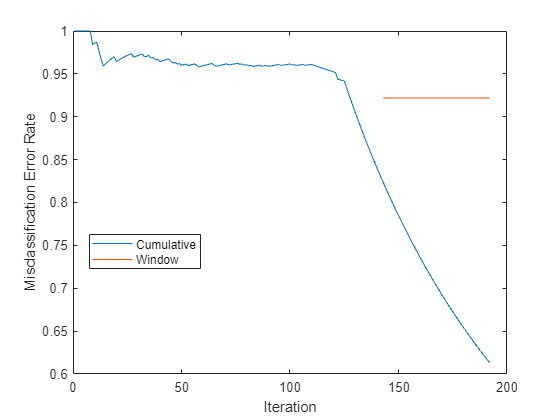



figure(2); 
plot(ce.Variables)
ylabel('Misclassification Error Rate')
legend(ce.Properties.VariableNames,'Location','best')
xlabel('Iteration')


 Mdl = updateMetrics(Mdl,data_te(:, 1:18),data_te(:,19));
    ce = Mdl.Metrics{"ClassificationError",:}

ce =     0.0605         0


output_test = predict(Mdl,data_te(:, 1:18));
accuracy = sum(output_test == data_te(:,19))/numel(data_te(:,19))

accuracy = 0.8091

precision = sum(output_test & data_te(:,19)) / sum(output_test)

precision = 1

recall = sum(output_test & data_te(:,19)) / sum(data_te(:,19))

recall = 0.6725

F1_score = 2 * (precision * recall) / (precision + recall)

F1_score = 0.8042

waktu = toc

waktu = 1.7368